clear all
load("filteredFlightData.mat")
input1

input1 =    -0.5950         0         0
   -0.5950         0         0
   -0.9100         0         0
   -1.7150         0         0
   -2.2050         0         0
   -2.2750         0         0
   -2.3100         0         0
   -2.2050         0         0
   -1.9250         0         0
   -2.0300         0         0


output1

output1 =    -0.4003   -1.4674  -11.3321
   -0.4152   -1.6502    6.7304
   -0.4018   -1.7620   -3.0196
   -0.4626   -1.8658  -15.8946
   -0.5348   -2.0015  -11.6446
   -0.6389   -2.1481   -6.0196
   -0.9104   -2.1149   -9.0821
   -1.2098   -2.0413  -13.4571
   -1.5462   -1.9434   -5.8321
   -1.7951   -1.8460   -5.0821


FemteOrdensSS

FemteOrdensSS =
 
  A = 
              x1         x2         x3         x4         x5
   x1   -0.05839      1.137     -5.328     0.1692      1.697
   x2    -0.5101     -4.365     -1.426     -2.729     0.7809
   x3      4.747    -0.5227     -1.307      2.255     0.6723
   x4     0.6217     -2.832    -0.9363     -3.096     -2.855
   x5  -0.001643     -9.471      3.834      5.383     -8.579
 
  B = 
        InputRoll  InputPitch    InputYaw
   x1     0.06131     0.01464    0.005031
   x2     -0.1972    -0.01376   -0.007468
   x3    -0.04282    0.002092    -0.02374
   x4     -0.2094     0.02003    -0.01638
   x5     -0.5735       0.101    -0.04603
 
  C = 
               x1       x2       x3       x4       x5
   Roll      3.69   -23.75  -0.3631  -0.5797   -1.126
   Pitch    107.4    4.216   -10.62   -0.941   0.9499
   Yaw      218.9   -184.8    79.52    357.7     12.8
 
  D = 
           InputRoll  InputPitch    InputYaw
   Roll            0           0           0
   Pitch           0    

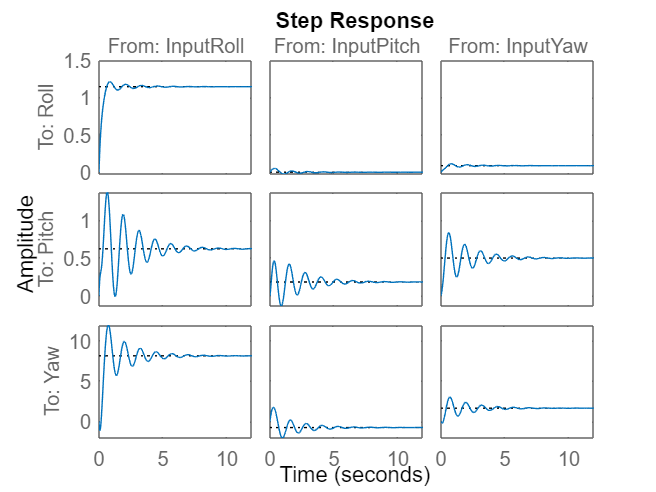

step(FemteOrdensSS)

H=tf(FemteOrdensSS)

H =
 
  From input "InputRoll" to output...
             5.693 s^4 + 63.55 s^3 + 450.7 s^2 + 1877 s + 6810
   Roll:  -------------------------------------------------------
          s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
              5.861 s^4 + 4.801 s^3 + 439.3 s^2 + 2092 s + 3690
   Pitch:  -------------------------------------------------------
           s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
         -35.79 s^4 + 52.33 s^3 + 888.2 s^2 + 1.24e04 s + 4.828e04
   Yaw:  ---------------------------------------------------------
          s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
  From input "InputPitch" to output...
            0.2548 s^4 + 4.03 s^3 + 23.17 s^2 + 119.9 s - 11.72
   Roll:  -------------------------------------------------------
          s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
             1.569 s^4 + 41.14 s^3 + 248.6 s^2 + 531.1 s + 1080
   Pitch:  ---------------------------------------------

clf
H_roll_Yaw=H(3,1)

H_roll_Yaw =
 
  From input "InputRoll" to output "Yaw":
  -35.79 s^4 + 52.33 s^3 + 888.2 s^2 + 1.24e04 s + 4.828e04
  ---------------------------------------------------------
   s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
Continuous-time transfer function.



pole(H_roll_Yaw)

ans =   -7.7665 + 0.0000i
  -0.5029 + 5.0483i
  -0.5029 - 5.0483i
  -4.3166 + 3.3440i
  -4.3166 - 3.3440i


zero(H_roll_Yaw)

ans =    9.4950 + 0.0000i
  -2.0054 + 5.5948i
  -2.0054 - 5.5948i
  -4.0219 + 0.0000i


step(H_roll_Yaw)
hold on
eig(1/H_roll_Yaw)

ans =    9.4950 + 0.0000i
  -2.0054 + 5.5948i
  -2.0054 - 5.5948i
  -4.0219 + 0.0000i


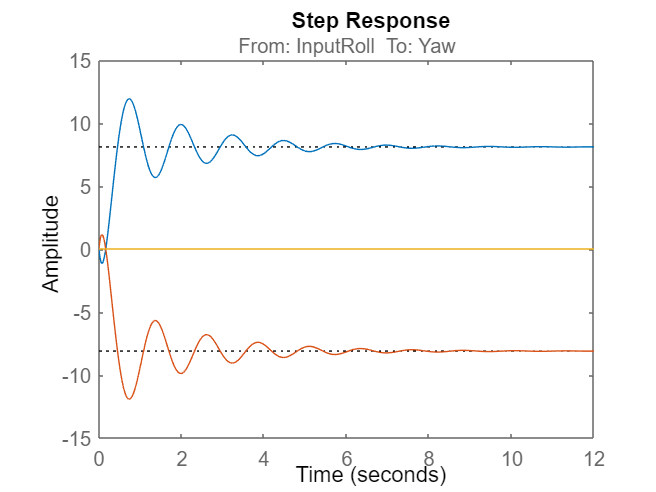

step(-1*H_roll_Yaw)
step(-1*H_roll_Yaw+H_roll_Yaw)
hold off

clf
H_pitch=H(:,2)

H_pitch =
 
  From input "InputPitch" to output...
            0.2548 s^4 + 4.03 s^3 + 23.17 s^2 + 119.9 s - 11.72
   Roll:  -------------------------------------------------------
          s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
             1.569 s^4 + 41.14 s^3 + 248.6 s^2 + 531.1 s + 1080
   Pitch:  -------------------------------------------------------
           s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
            14.37 s^4 + 166.8 s^3 + 1022 s^2 + 3079 s - 4608
   Yaw:  -------------------------------------------------------
         s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
Continuous-time transfer function.



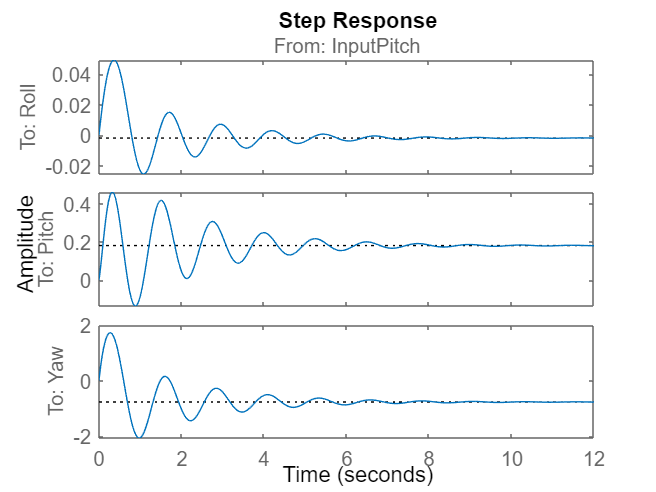

step(H_pitch)

s=tf('s');
clf
tau_d=1/0.5

tau_d = 2

tau_n=0

tau_n = 0

%tau_d=1/2
%tau=1/7.76
%tau=1/4.316
H_firstOrder=(s*tau_n+1)/(s*tau_d+1)

H_firstOrder =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.



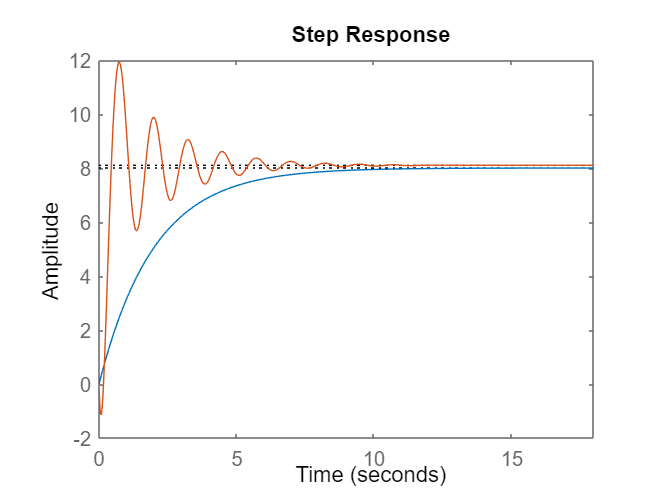

step(H_firstOrder*8)
hold on
step(H_roll_Yaw)

%step(H_roll_Yaw-H_firstOrder*8)



clear all
clf
syms s t
H_roll_Yaw=(-35.79*s^4 + 52.33*s^3 + 888.2*s^2 + 1.24e04*s + 4.828e04)/(s^5 + 17.41*s^4 + 139.1*s^3 + 751.1*s^2 + 2726*s + 5960)

$$H\_roll\_Yaw = \frac{-\frac{3579\,s^{4}}{100}+\frac{5233\,s^{3}}{100}+\frac{4441\,s^{2}}{5}+12400\,s+48280}{s^{5}+\frac{1741\,s^{4}}{100}+\frac{1391\,s^{3}}{10}+\frac{7511\,s^{2}}{10}+2726\,s+5960}$$

 
step_time(t)=ilaplace(H_roll_Yaw*1/s,s,t)

$$step\_time(t) = \begin{array}{l} \frac{1207}{149}-\frac{144268200\,\left(\sum_{k=1}^{5}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{\sigma_{1}}\right)}{149}-\frac{16009653\,\left(\sum_{k=1}^{5}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{\sigma_{1}}\right)}{149}-\frac{2634658\,\left(\sum_{k=1}^{5}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{3}}{\sigma_{1}}\right)}{149}-\frac{120700\,\left(\sum_{k=1}^{5}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{4}}{\sigma_{1}}\right)}{149}-\frac{77423590\,\left(\sum_{k=1}^{5}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{2\,\left(75110\,\sigma_{2}+20865\,{\sigma_{2}}^{2}+3482\,{\sigma_{2}}^{3}+250\,{\sigma_{2}}^{4}+136300\right)}\right)}{149}\\ \mathrm{where}\\ \sigma_{1}=2\,\left(250\,{\sigma_{2}}^{4}+3482\,{\sigma_{2}}^{3}+20865\,{\sigma_{2}}^{2}+75110\,\sigma_{2}+136300\right)\\ \sigma_{2}=\mathrm{root}\left(z^{5}+\frac{1741\,z^{4}}{100}+\frac{1391\,z^{3}}{10}+\frac{7511\,z^{2}}{10}+2726\,z+5960,z,k\right) \end{array}$$

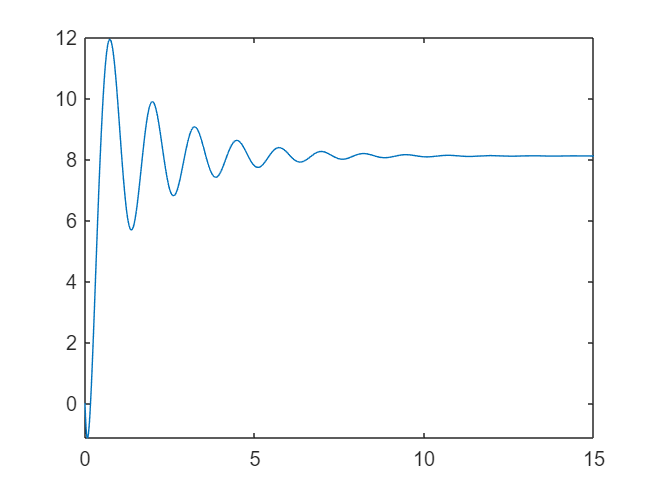

fplot(step_time(t), [0 15])

time=0:0.1:15

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


sampleStep=eval(vpa(step_time(time)))'

sampleStep =          0
   -1.0122
    0.8845
    3.7879
    6.7756
    9.3174
   11.0761
   11.8753
   11.7135
   10.7644


ref=(ones(1,length(time))*8)'

ref =      8
     8
     8
     8
     8
     8
     8
     8
     8
     8


clf
s=tf('s');
H_roll_Yaw=(-35.79*s^4 + 52.33*s^3 + 888.2*s^2 + 1.24e04*s + 4.828e04)/(s^5 + 17.41*s^4 + 139.1*s^3 + 751.1*s^2 + 2726*s + 5960)

H_roll_Yaw =
 
   -35.79 s^4 + 52.33 s^3 + 888.2 s^2 + 12400 s + 48280
  -------------------------------------------------------
  s^5 + 17.41 s^4 + 139.1 s^3 + 751.1 s^2 + 2726 s + 5960
 
Continuous-time transfer function.



step(H_roll_Yaw)
hold on
step(tf2*8)
tf2

tf2 =
 
  From input "u1" to output "y1":
    4.586
  ---------
  s + 4.496
 
Name: tf2
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 36.34% (stability enforced)
FPE: 0.8488, MSE: 0.8158                           


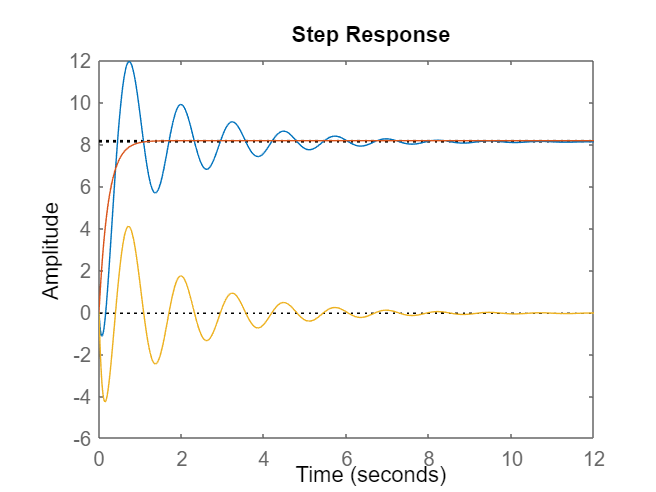

step(H_roll_Yaw-tf2*8)